clc                     % clear command window
clear                   % clear MATLAB workspace
format long

waypoints = [42.2932850000000	-71.2643730000000;
42.2933450000000	-71.2643800000000;
42.2934050000000	-71.2643620000000;
42.2934650000000	-71.2643310000000;
42.2935240000000	-71.2642900000000;
42.2935800000000	-71.2642390000000;
42.2936290000000	-71.2641810000000;
42.2936710000000	-71.2641130000000;
42.2937100000000	-71.2640390000000;
42.2937410000000	-71.2639610000000;
42.2937630000000	-71.2638790000000;
42.2937790000000	-71.2637920000000;
42.2937770000000	-71.2636910000000;
42.2937460000000	-71.2636020000000;
42.2937050000000	-71.2635460000000;
42.2936520000000	-71.2635150000000;
42.2935930000000	-71.2635070000000;
42.2935280000000	-71.2635240000000;
42.2934440000000	-71.2635980000000;
42.2933960000000	-71.2636300000000;
42.2933390000000	-71.2636580000000;
42.2932820000000	-71.2637380000000;
42.2932400000000	-71.2638090000000;
42.2932060000000	-71.2638850000000;
42.2931780000000	-71.2639680000000;
42.2931590000000	-71.2640510000000;
42.2931490000000	-71.2641330000000;
42.2931520000000	-71.2642070000000;
42.2931860000000	-71.2642850000000;
42.2932290000000	-71.2643390000000]

waypoints =   42.293284999999997 -71.264373000000006
  42.293345000000002 -71.264380000000003
  42.293405000000000 -71.264362000000006
  42.293464999999998 -71.264330999999999
  42.293523999999998 -71.264290000000003
  42.293579999999999 -71.264239000000003
  42.293629000000003 -71.264180999999994
  42.293671000000003 -71.264112999999995
  42.293709999999997 -71.264038999999997
  42.293740999999997 -71.263960999999995



save("final_waypoints.mat", "waypoints")

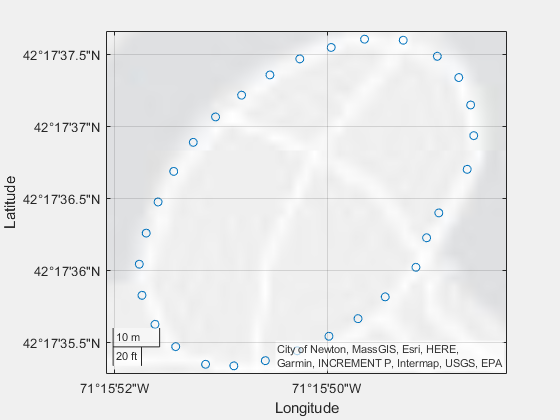

geoscatter(waypoints(:,1),waypoints(:,2))

**LATITUDE LONGITUDE TESTING**

plots gps coordinates in terms of meters

alt = 10;
% origin found on google maps on the bottom left corner of the oval.
origin = [42.29313067072105, -71.26442435650652, alt];

[xEast,yNorth] = latlon2local(waypoints(:,1), waypoints(:,2),alt,origin)

xEast =    4.235338213895992
   3.658049223799370
   5.142491409479160
   7.699029403445263
  11.080253185100643
  15.286161090930161
  20.069346081553260
  25.677214969706398
  31.779890722910892
  38.212438799708075


yNorth =   17.142767153459943
  23.807516247336000
  30.472266663811233
  37.137018558356957
  43.690693545442770
  49.911134489357451
  55.354025497297926
  60.019368630387220
  64.351481003465821
  67.794967176012989


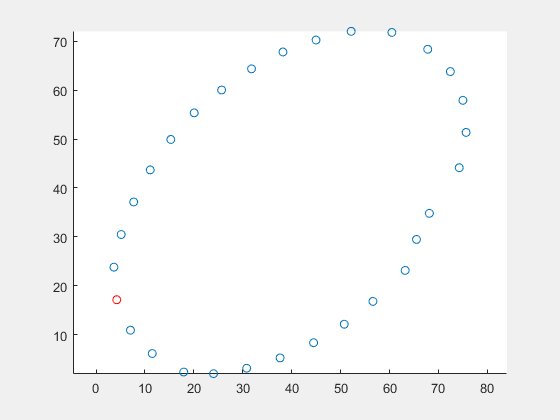

scatter(xEast,yNorth)
hold on
scatter(xEast(1),yNorth(1), "r")
hold off
axis('equal');

% min(xEast)
% max(xEast)
% min(yNorth)
% max(yNorth)

find proper grid size of the occupancy grid

gridsize = [round(max(xEast)+5), round(max(yNorth)+5)]

gridsize =     81    77


CREATE NEW OCCUPANCY GRID WITH ADJUSTED GRID SIZE

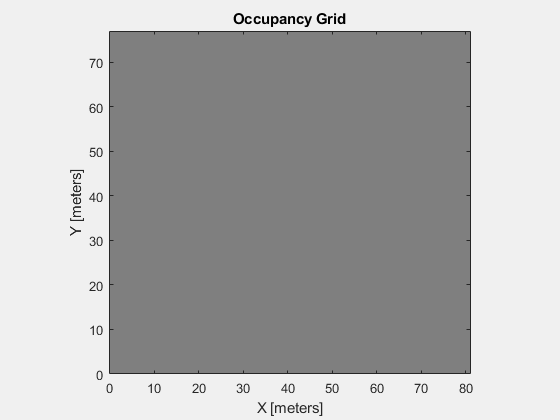

res = 10; % resolution in cells per meter, so there are 10*10 = 100 cells in one meter
roverOccupancyGrid = occupancyMap(gridsize(1), gridsize(2), res);

% Create free floating figure (Rover occupancy grid)
figureRoverOccupancy = figure('name', 'RoverOccupancyGrid', 'NumberTitle', 'off', 'Visible', 'on');
figure(figureRoverOccupancy);                            
    show(roverOccupancyGrid);  

TEST PLOTTING ONE GPS POINT

Note: all testing done by setting value to 1 because inflate only works on values of 1

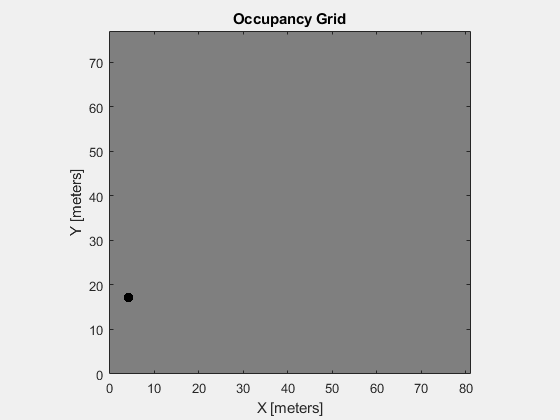

GPS_Point = [42.2932850000000	-71.2643730000000];
[grid_x,grid_y] = latlon2local(GPS_Point(1), GPS_Point(2),alt,origin);
updateOccupancy(roverOccupancyGrid, [grid_x grid_y], 1);
inflate(roverOccupancyGrid, 1); % NOTE: inflates only values at 1
figure(figureRoverOccupancy);                            
    show(roverOccupancyGrid);

TEST PLOTTING ALL WAYPOINTS ON NEW OCCUPANCY GRID USING GPSTOGRID FUNCTION

% plot waypoints by setting color as 1
p = 1;
for i = 1:length(waypoints)
    gridCoord = GPSToGrid(waypoints(i,:))
    updateOccupancy(roverOccupancyGrid,[gridCoord.x,gridCoord.y],1);
end

gridCoord = struct with fields:
    x: 4.235338213895992
    y: 17.142767153459943


gridCoord = struct with fields:
    x: 3.658049223799370
    y: 23.807516247336000


gridCoord = struct with fields:
    x: 5.142491409479160
    y: 30.472266663811233


gridCoord = struct with fields:
    x: 7.699029403445263
    y: 37.137018558356957


gridCoord = struct with fields:
    x: 11.080253185100643
    y: 43.690693545442770


gridCoord = struct with fields:
    x: 15.286161090930161
    y: 49.911134489357451


gridCoord = struct with fields:
    x: 20.069346081553260
    y: 55.354025497297926


gridCoord = struct with fields:
    x: 25.677214969706398
    y: 60.019368630387220


gridCoord = struct with fields:
    x: 31.779890722910892
    y: 64.351481003465821


gridCoord = struct with fields:
    x: 38.212438799708075
    y: 67.794967176012989


gridCoord = struct with fields:
    x: 44.974861867696362
    y: 70.238748873195433


gridCoord = struct with fields:
    x: 52.149628717471487
    y: 72.016065147117729


gridCoord = struct with fields:
    x: 60.478970877989703
    y: 71.793973615748769


gridCoord = struct with fields:
    x: 67.818720031095893
    y: 68.350586535413385


gridCoord = struct with fields:
    x: 72.437017481384203
    y: 63.796386897603611


gridCoord = struct with fields:
    x: 74.993613526315798
    y: 57.909218044226819


gridCoord = struct with fields:
    x: 75.653435184399285
    y: 51.355554508481703


gridCoord = struct with fields:
    x: 74.251539248424166
    y: 44.135394032852638


gridCoord = struct with fields:
    x: 68.148920641837833
    y: 34.804682689565780


gridCoord = struct with fields:
    x: 65.509957509241346
    y: 29.472857941874679


gridCoord = struct with fields:
    x: 63.200876477709485
    y: 23.141324773946685


gridCoord = struct with fields:
    x: 56.603384369553460
    y: 16.809756549557790


gridCoord = struct with fields:
    x: 50.748093264870533
    y: 12.144387243184278


gridCoord = struct with fields:
    x: 44.480441382285214
    y: 8.367653467080931


gridCoord = struct with fields:
    x: 37.635492635120805
    y: 5.257397116048236


gridCoord = struct with fields:
    x: 30.790533441038878
    y: 3.146859837011176


gridCoord = struct with fields:
    x: 24.028036259258009
    y: 2.036041901546341


gridCoord = struct with fields:
    x: 17.925289654218538
    y: 2.369261131548897


gridCoord = struct with fields:
    x: 11.492659874954239
    y: 6.145938896637412


gridCoord = struct with fields:
    x: 7.039302683041384
    y: 10.922336679602598


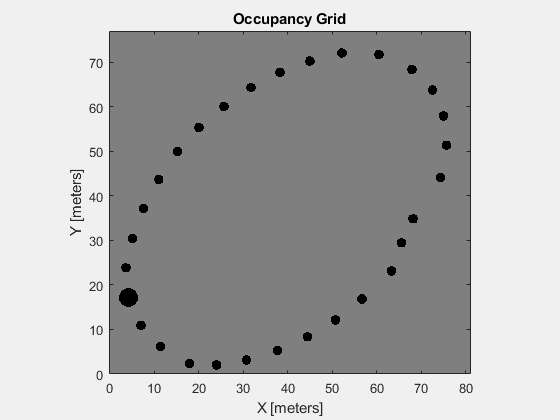

inflate(roverOccupancyGrid, 1); % helps waypoints show up better

% Create free floating figure (Rover occupancy grid)
figure(figureRoverOccupancy);                            
    show(roverOccupancyGrid);

function [gridCoordinate] = GPSToGrid(GPSCoordinate)
    altitude = 10;
    % origin is at the bottom left corner
    origin = [42.29313067072105, -71.26442435650652, altitude];
    [gridCoordinate.x,gridCoordinate.y] = latlon2local(GPSCoordinate(1), GPSCoordinate(2),altitude,origin);
end